# Attitude representation 

The most common ways to represent attitude are: rotation matrix, Euler angles, and Quaternion

There following **factors** affect the final equations/matrices that represent attitude and perform coordinate transformations:

- Wether the rotation matrix represnt body-fixed frame to world frame transformation or vice versa (the relationship between them is the transpose).

- Wether the rotation matrix active vs assive. A passive rotation matrix takes the space associated with the rotated system and evaluate it wrt to the fixed system (wolrd to body), while an active rotation evaluates the fixed system wrt to the rotated one (body to world).

- Wether rotation sequence is internsic or extrinsic (the relationship is reverse order)

- Wether the angles are positive clockwise or counterclockwise

# **PASSIVE** rotations vs **ACTIVE** rotations

- A **PASSIVE** rotation matrix ${^BR_G}$, converts the co-ordinates of a point expressed in a fixed **G-frame**, into the co-ordinates of the same point expressed in the new **B-frame**. 

- vb = pR3X(psi) * pR2Y(theta) * pR1Z(phi) * vg

- vb = bRg * vg

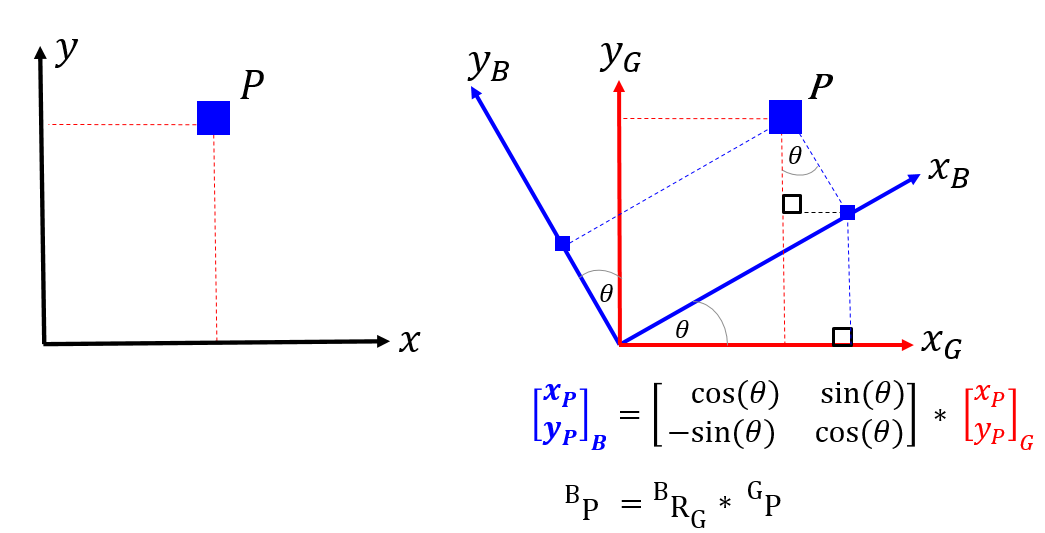

- An **ACTIVE** rotation matrix ${^GR_B}$, allows us to calculate the position of the new point in B-frame relative to the G-frame, ie: ${^GP}$. 

- vg = inv(pR1Z(phi)) * inv(pR2Y(theta)) * inv(pR3X(psi)) * vb

- vg = gRb * vb

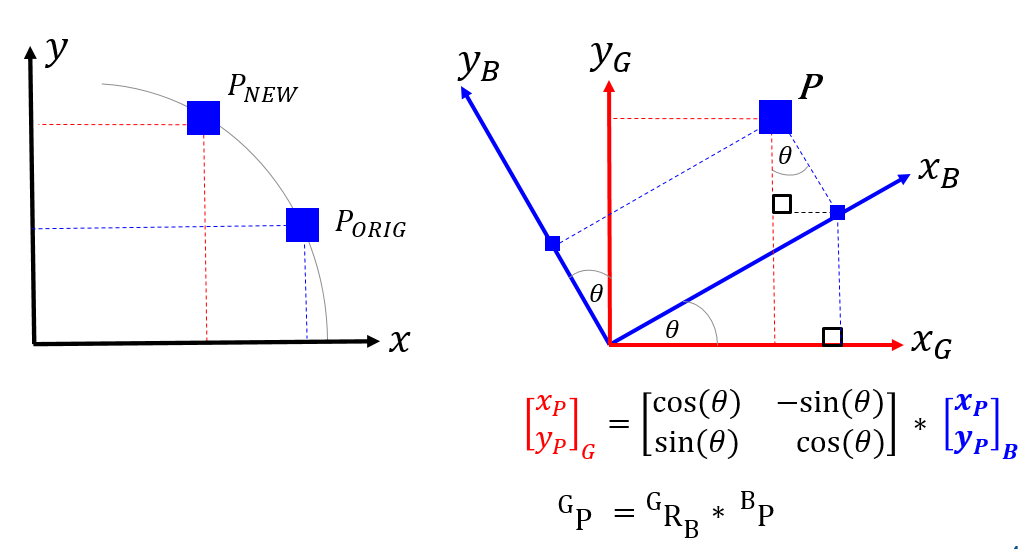

- Passive rotation is related to active rotation by the transpose:


$${}^BR_G={}^GR^T_B$$


# Rotation matrix (Direction Cosine Matrix)

- Uses a 3×3 matrix to represent the linear transform mapping from one coordinate frame to another rotated coordinate frame.

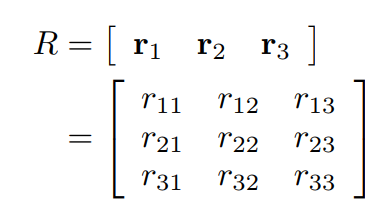

- Some authors prefer to write the matrix that maps from the body-flxed coordinates to the world coordinates; others prefer the matrix that maps from the world coordinates to the body-flxed coordinates.  

- *rotation matrix (here) *encodes the attitude of a rigid body to be the matrix that when pre-multiplied by a vector expressed in the world coordinates yields the same vector expressed in the body-flxed coordinates $\acute{z}$ is in world frame, z is in body frame. 

  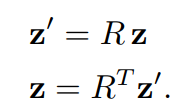

- Rotation matrices are a complete representation of a 3D orientation, thus there is no singularity in that model.

- A *coordinate rotation *is a rotation about a single coordinate axis. Enumerating the *x*-, *y*-, and *z*-axes with 1,2,and 3, the coordinate rotations (passive) are:

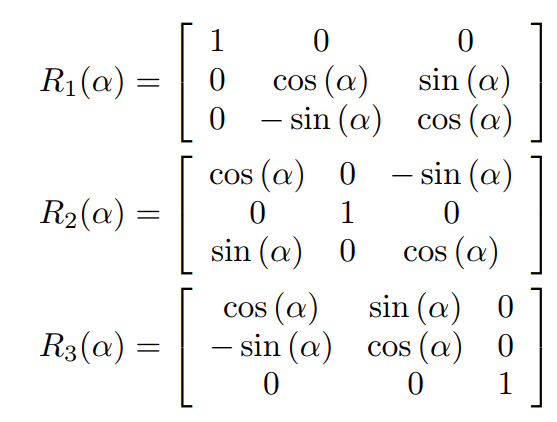

-  A rotation matrix may also be referred to as a *direction cosine matrix *, because the elements of this matrix are the cosines of the unsigned angles between the body-flxed axes and the world axes. 

- An example of 3 successive PASSIVE rotations

# Euler angles

Euler angles are widely used because they are easy to understand. The three parameters : Roll, Pitch and Yaw define rotations around the fixed frame's axes :

- Roll (φ) : Rotation around X axis defined between [-π ; π] ;

- Pitch (θ) : Rotation around Y axis defined between [-π/2 ; π/2] ;

- Yaw (ψ) : Rotation around Z axis defined between [-π ; π].

### Gimbal lock

Euler angles suffer from a singularity called "Gimbal lock”, when Pitch approaches ± π/2,we do not advise to use Euler angles if the device has to be used in a wide range of orientations. Quaternions and rotation matrices do not have any singularity.

### **Rotation Sequence**  

Three coordinate rotations in sequence can describe any rotation.  The function that maps an Euler angle vector to its corresponding rotation matrix

**The table below summarizes some of the popular rotation sequences:**

- 1, 2, 3 represent the angles *α*, *β* and *γ*, i.e. the angles corresponding to the first, second and third elemental rotations respectively.

- *X*, *Y*, *Z* are the matrices representing the elemental rotations about the axes *x*, *y*, *z* of the fixed frame (e.g., *X*1 represents a rotation about *x* by an angle *α*).

- *s* and *c* represent sine and cosine (e.g., *s*1 represents the sine of *α*).

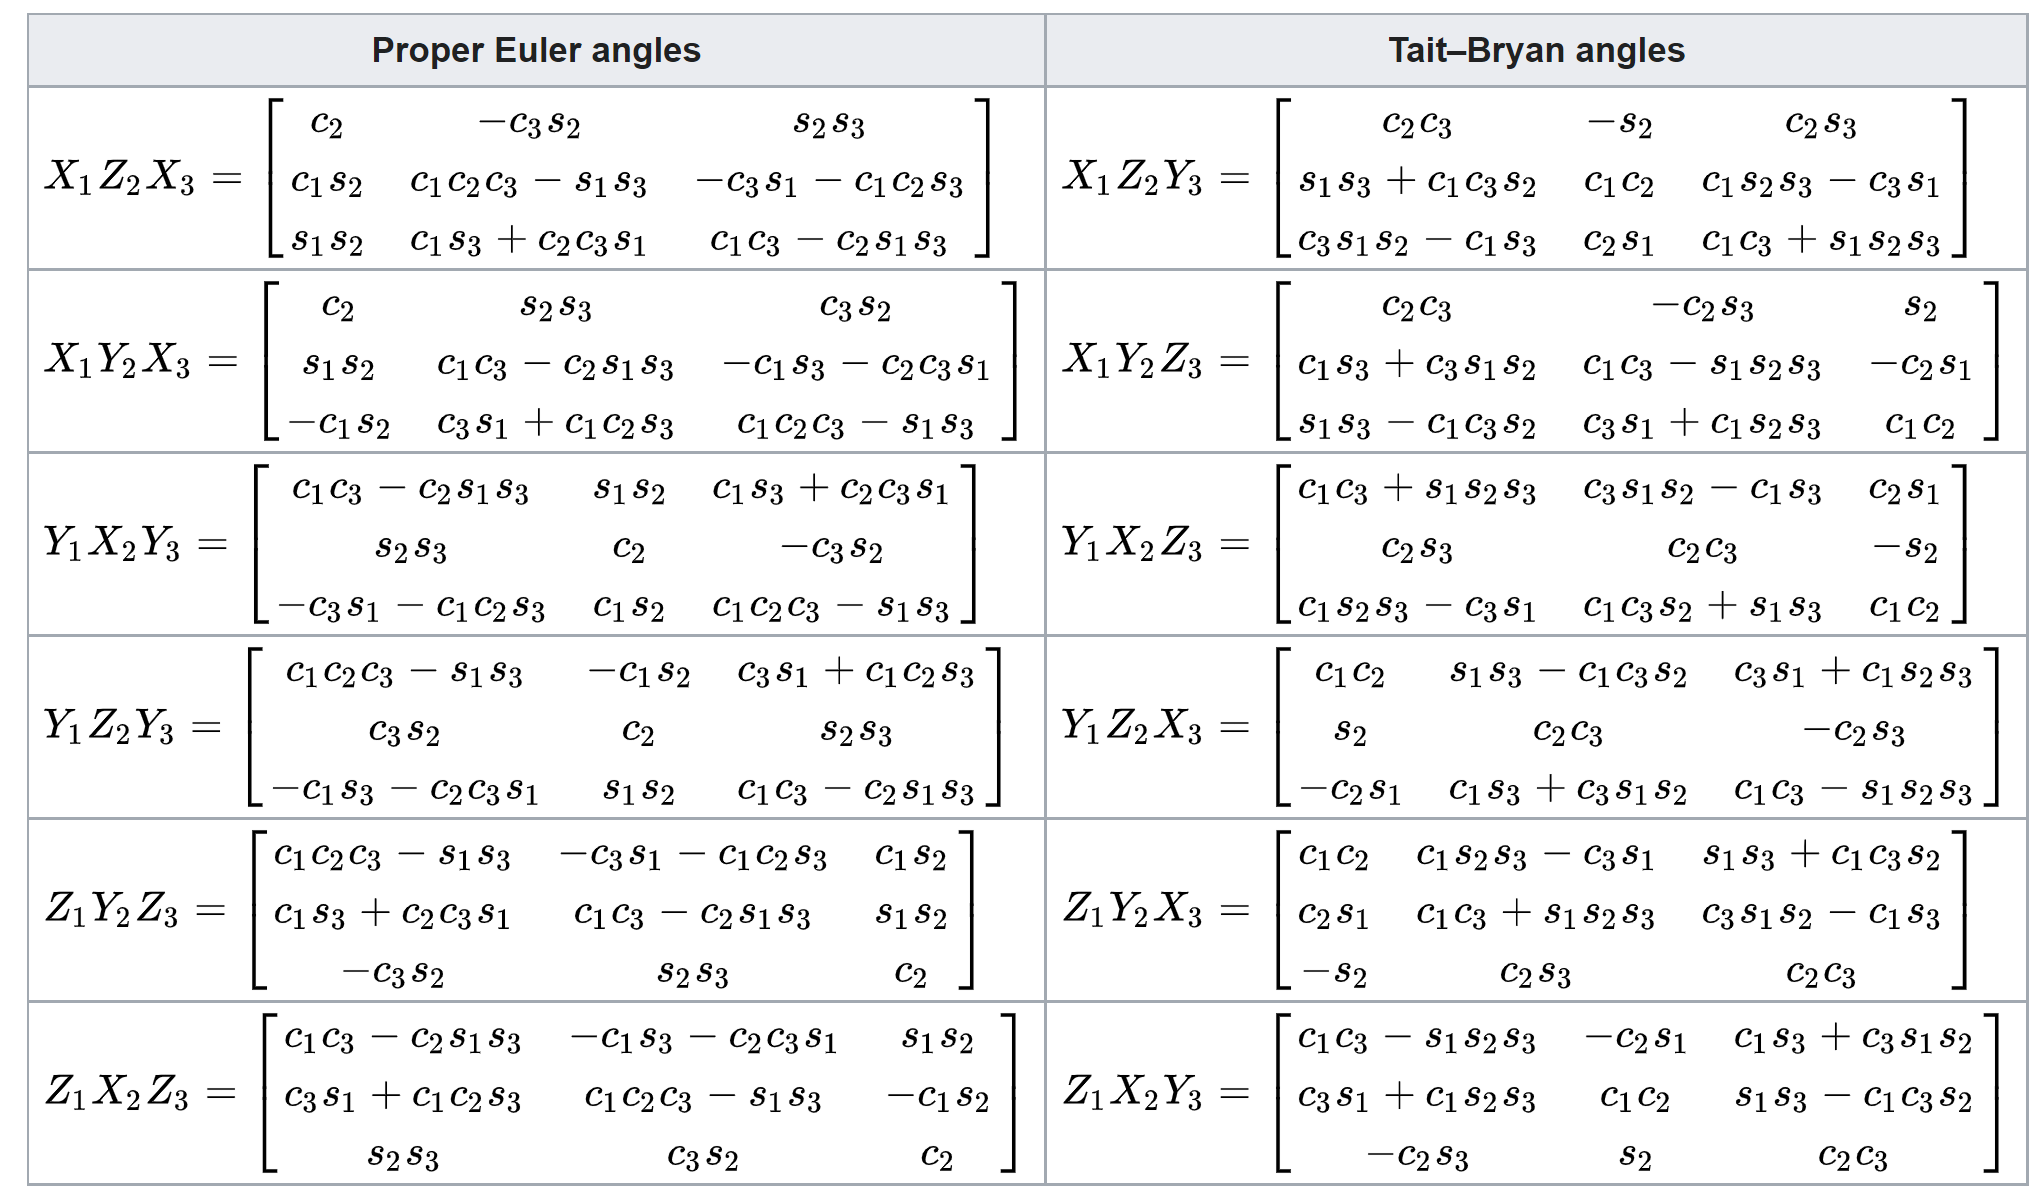

**Refer to **[https://en.wikipedia.org/wiki/Euler_angles](https://en.wikipedia.org/wiki/Euler_angles) for more details

## Euler angle rates from body rates (pqr)

This depends on the euler angle sequenc used

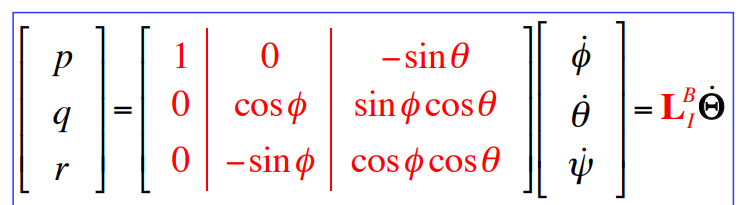

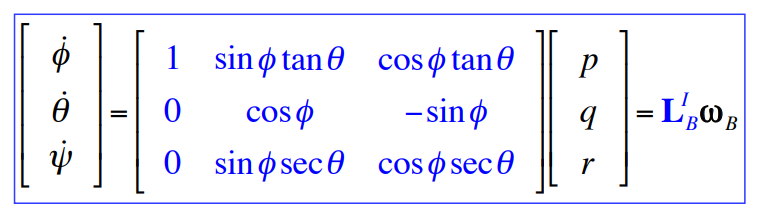

# Quaternions

- Quaternions can be represented by Eignaxis representation which has a rotation axis $\overrightarrow{E}$and a rotation angle $\theta \;$around this axis.

- the relationship between the quaternion and the Eigenaxis parameters $\left\lbrace \theta \;,\overrightarrow{E} \right\rbrace$


$$\left\lbrack \begin{array}{c}
q_0 \\
q_X \\
q_Y \\
q_Z 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\cos \left(\frac{\theta }{2}\right)\\
E_X \ldotp \sin \left(\frac{\theta }{2}\right)\\
E_Y \ldotp \sin \left(\frac{\theta }{2}\right)\\
E_Z \ldotp \sin \left(\frac{\theta }{2}\right)
\end{array}\right\rbrack$$


where:

- 
$$\;\left(\;1\;\;=\;\;\;{E_X }^2 \;+\;\;\;{E_Y }^2 \;+\;\;{E_Z }^2 \;\right)\;\;\;\;\;\textrm{and}\;\;\;\;\left(\;1\;\;=\;\;{q_0 }^2 +\;\;\;\;{q_X }^2 \;+\;\;\;{q_Y }^2 \;+\;\;{q_Z }^2 \;\right)$$


## Quaternion inverse

Note: Inverse is the same as conjugate if it is a unit quaternion, hence make sure to nromalize quaternion.

if $q=\left\lbrack \begin{array}{c}
q_0 \\
q_X \\
q_Y \\
q_Z 
\end{array}\right\rbrack$then $q^{-1} =\left\lbrack \begin{array}{c}
q_0 \\
{-q}_X \\
-q_Y \\
-q_Z 
\end{array}\right\rbrack$

## Quaternion multiplication


$$q\otimes p=Q\left(q\right)p=\left\lbrack \begin{array}{cccc}
q_0  & -q_1  & -q_2  & -q_3 \\
q_1  & q_0  & q_3  & -q_2 \\
q_2  & -q_3  & q_0  & q_1 \\
q_3  & q_2  & -q_1  & q_0 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
p_0 \\
p_1 \\
p_2 \\
p_3 
\end{array}\right\rbrack$$


## Quaternion transformation

To transform a vector (i.e. position, velocity,etc.) from a certain coordinate frame to another coordinate frame use the following formula

### 
$$P_B ={q\otimes P}_A \otimes q^{-1}$$
 

 where q represent the rotation from A to B

To perform the transformation in the opposite direction, inverse the quaternion then apply the same formula above

## Quaternion to DCM conversion

- Rotation matrix can be extracted from quaternion. The following rotation matrix represent transformation from the world frame to body-fixed frame.

- Note: this transformation is independent of Euler angle sequences. You could see it differently only if the quaternion is represented differently (i.e. q0 is swapped with q3)


$${}^BR_G=\left(\begin{array}{ccc}
{q_0 }^2 +{q_X }^2 -{q_Y }^2 -{q_Z }^2  & 2\,q_0 \,q_Z +2\,q_X \,q_Y  & 2\,q_X \,q_Z -2\,q_0 \,q_Y \\
2\,q_X \,q_Y -2\,q_0 \,q_Z  & {q_0 }^2 -{q_X }^2 +{q_Y }^2 -{q_Z }^2  & 2\,q_0 \,q_X +2\,q_Y \,q_Z \\
2\,q_0 \,q_Y +2\,q_X \,q_Z  & 2\,q_Y \,q_Z -2\,q_0 \,q_X  & {q_0 }^2 -{q_X }^2 -{q_Y }^2 +{q_Z }^2 
\end{array}\right)$$


## The derivatives of the quaternion parameters


$$\left\lbrack \begin{array}{c}
\dot{q_0 } \\
\dot{q_X } \\
\dot{q_Y } \\
\dot{q_Z } 
\end{array}\right\rbrack =\;B\;\;\ldotp \;\;{\left\lbrack \begin{array}{c}
\omega_x \\
\omega_y \\
\omega_z 
\end{array}\right\rbrack }_B$$



$$B=\left(\begin{array}{ccc}
-\frac{q_x }{2} & -\frac{q_y }{2} & -\frac{q_z }{2}\\
\frac{q_0 }{2} & -\frac{q_z }{2} & \frac{q_y }{2}\\
\frac{q_z }{2} & \frac{q_0 }{2} & -\frac{q_x }{2}\\
-\frac{q_y }{2} & \frac{q_x }{2} & \frac{q_0 }{2}
\end{array}\right)$$


- Note the B matrix can map the quaternion rates to the angular velocity in body frame. Similar approach can produce the mapping to angular velocity in world frame

- We can also express $\dot{q}$ in an alternate form


$$\left\lbrack \begin{array}{c}
\dot{q_0 } \\
\dot{q_X } \\
\dot{q_Y } \\
\dot{q_Z } 
\end{array}\right\rbrack =A\;\ldotp \;\;\left\lbrack \begin{array}{c}
q_0 \\
q_x \\
q_y \\
q_z 
\end{array}\right\rbrack$$


A=$\left(\begin{array}{cccc}
0 & -\frac{\omega_x }{2} & -\frac{\omega_y }{2} & -\frac{\omega_z }{2}\\
\frac{\omega_x }{2} & 0 & \frac{\omega_z }{2} & -\frac{\omega_y }{2}\\
\frac{\omega_y }{2} & -\frac{\omega_z }{2} & 0 & \frac{\omega_x }{2}\\
\frac{\omega_z }{2} & \frac{\omega_y }{2} & -\frac{\omega_x }{2} & 0
\end{array}\right)$

### Quaternion to Euler angles

- Quaternions can be converted to Euler angles. Different equations are available depending on the euler angle sequence, for example below is for sequence 1,2,3 (ZYX)

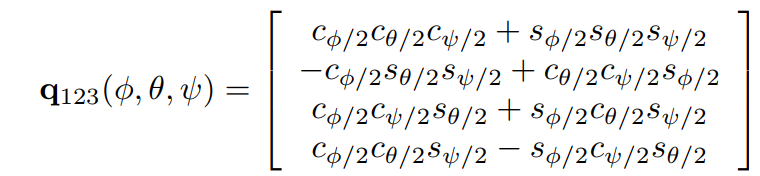

# Derivative of rotation matrix

- Recall that skew symmetric matrix is defined as:

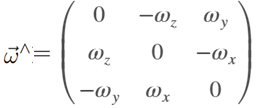

- ِAlso recall that ske symmetric matrix converts vector cross product to matrix multiplication $\hat{\mathit{\mathbf{A}}} \mathit{\mathbf{B}}=\mathit{\mathbf{A}}\times \mathit{\mathbf{B}}$ where $A={\left\lbrack x,y,z\right\rbrack }^T$

The derivative is related to the angular velocity by:

The velocity is related to position:${}^Gv={}^G{\;\omega }^ˆ_B\;\ldotp {}^G{p\left(t\right)}$

The significance of this expression for ${\dot{ {^GR_B} }}$, is that we can use it as a mechanism to propagate the orientation of a rigid body.  Using this approach there are NO singularities that would prevent us from computing ${^GR_B}(t) }$.  The implementation of this algorithm would look something like this:

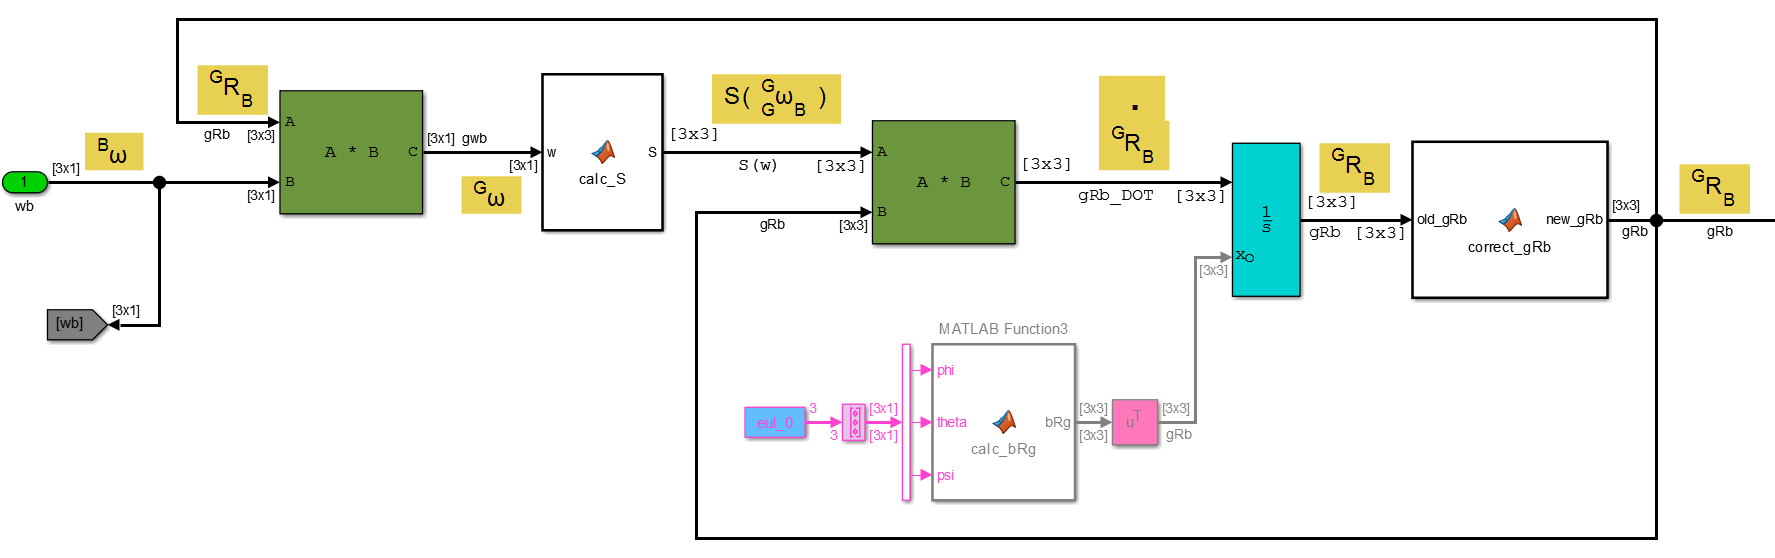

Note that to compute ${^GR_B}(t=0) }$, we could let the user specify an initial Euler angle configuration.  Also, the `calc_S` function would be:

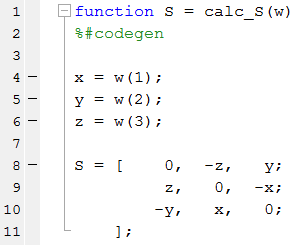

When we integrate ${\dot{ {^GR_B} }}$, we would expect that the orthogonality relationship of $\matrix{
  {^GR_B(t)} } \enspace . \thinspace {^GR_B(t)^T}= I 
}   $ would still  be true.  And it almost is !  The combination of "numerically" intergrating a derivative and the finite word size of computer calculations, means that we end up with a relationship that is more like this:

   
$$\matrix{
  {^GR_B(t)} } \enspace . \thinspace {^GR_B(t)^T}= I + \delta e \enspace \text{,where } \quad  \delta e \quad \text{ is a matrix of small terms}}
}   $$


We can reduce this $\delta e$ term using a correction technique such as the one proposed by William Premerlani and Paul Bizard (https://wiki.paparazziuav.org/w/images/e/e5/DCMDraft2.pdf).

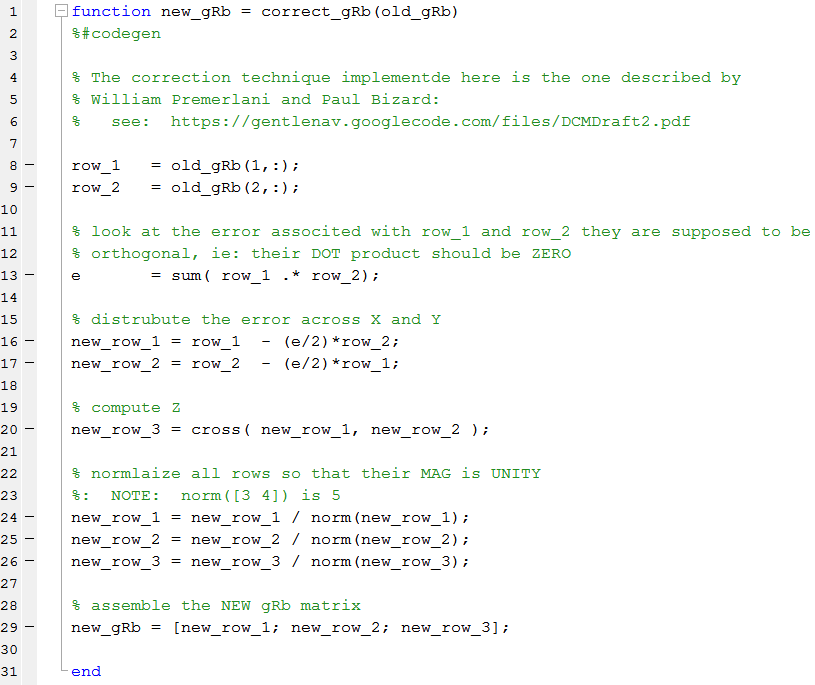

# Attitude representation using Euler angles

syms t
syms phi(t) theta(t) psi(t) p(t) q(t) r(t) % roll pitch yaw p q r
syms phi_dot(t)  theta_dot(t)  psi_dot(t) % euler rates
syms p_dot(t) q_dot(t) r_dot(t) % body rates

Let's use the Z - X - Y Euler angle convention

R1_z = [ 
      cos(psi),  -sin(psi),   0;
     sin(psi),  cos(psi),   0;
          0   ,     0    ,   1;
      
    ];
R2_x = [ 
         1   ,       0     ,     0      ;
         0   ,  cos(phi)   ,  -sin(phi);
         0   ,  sin(phi)  , cos(phi);   
    ];
R3_y = [ 
         cos(theta) ,   0     , sin(theta);
            0       ,   1     ,     0    ;      
        -sin(theta)  ,   0     , cos(theta);
      
    ];

Body to world(inertial) frame rotation

wRb = R1_z*R2_x*R3_y % body to world

$$wRb(t) = \left(\begin{array}{ccc} \cos\left(\psi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)-\sin\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right) & \cos\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)+\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\\ \cos\left(\theta \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)+\cos\left(\psi \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\psi \left(t\right)\right) & \sin\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-\cos\left(\psi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\\ -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & \sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) \end{array}\right)$$

bRw=transpose(wRb) % world to body

$$bRw(t) = \left(\begin{array}{ccc} \cos\left(\psi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)-\sin\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)+\cos\left(\psi \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\\ -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\psi \left(t\right)\right) & \sin\left(\varphi \left(t\right)\right)\\ \cos\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)+\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right) & \sin\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-\cos\left(\psi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) \end{array}\right)$$

## Orthogonality

rotation matrix is orthogonal


$$R^T \left(t\right)R\left(t\right)=R\left(t\right)R^T \left(t\right)=1$$


## Position & Velocity

syms R(t) R_t(t) % R and R transpose

Let's differentiate both sides of $R^T \left(t\right)R\left(t\right)=R\left(t\right)R^T \left(t\right)=1$

exp = diff(R_t*R ==1,t) == diff(R*R_t ==1,t)

$$exp(t) = \left(R\left(t\right)\,\frac{\partial }{\partial t}R_{t}\left(t\right)+R_{t}\left(t\right)\,\frac{\partial }{\partial t}R\left(t\right)=0\right)=\left(R\left(t\right)\,\frac{\partial }{\partial t}R_{t}\left(t\right)+R_{t}\left(t\right)\,\frac{\partial }{\partial t}R\left(t\right)=0\right)$$

### Position

Let's write the position equation as

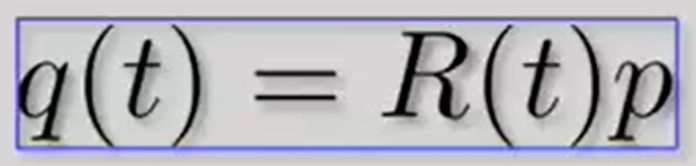

where p is position in fixed-body frame, q is position in inertial frame and R body to inertial transform

syms q_w(t)  p_b
position = q_w==R*p_b

$$position(t) = q_{w}\left(t\right)=p_{b}\,R\left(t\right)$$

### Velocity

If we differentiate, the result is

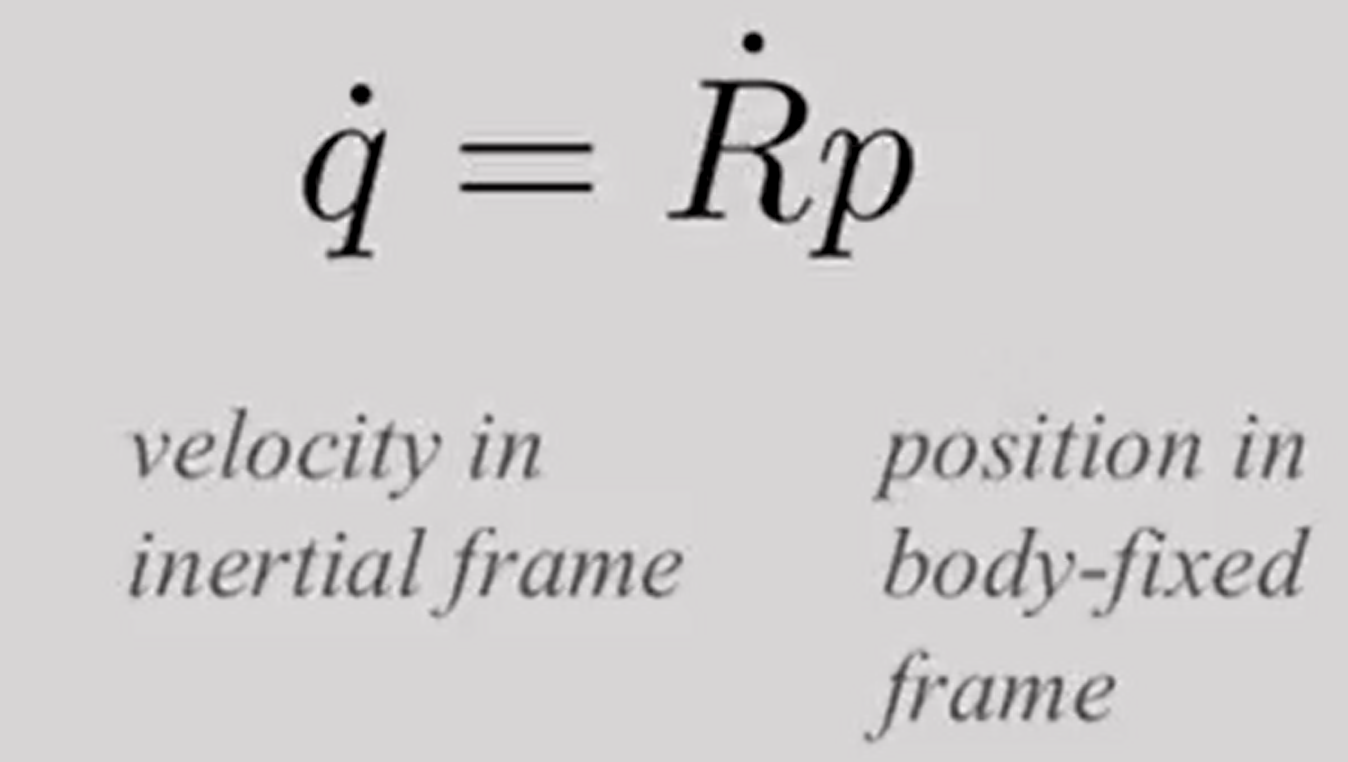

diff(position,t)

$$ans(t) = \frac{\partial }{\partial t}q_{w}\left(t\right)=p_{b}\,\frac{\partial }{\partial t}R\left(t\right)$$

Pre-multiply by rotation matrix transpose $R^T$ results in 

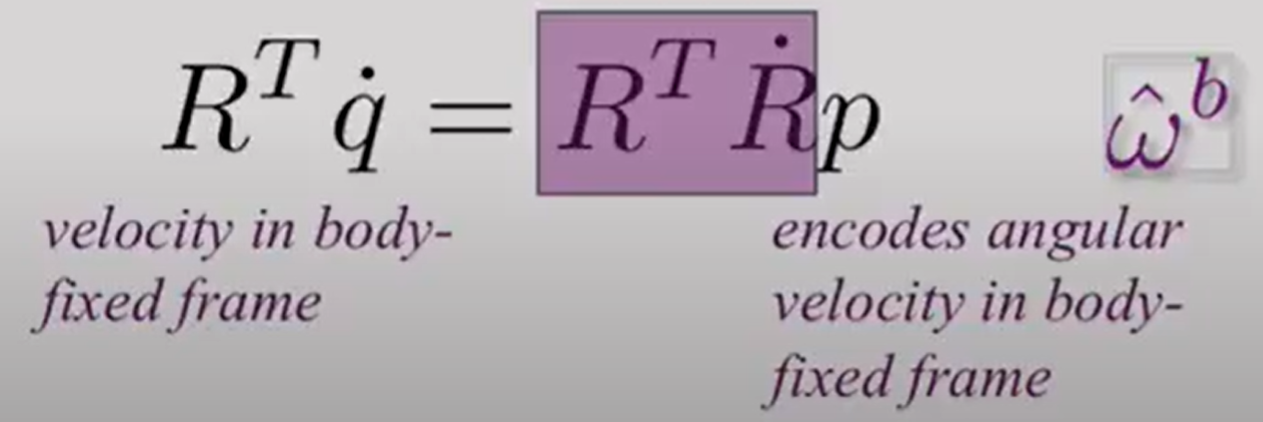

which relates body angular rates ($\omega_b$) to body-fixed velocity (transitional).

### 
$${\omega_b \;=R}^T \left(t\right)\dot{\;R} \left(t\right)$$


If we use $p=R^T q$, we get 

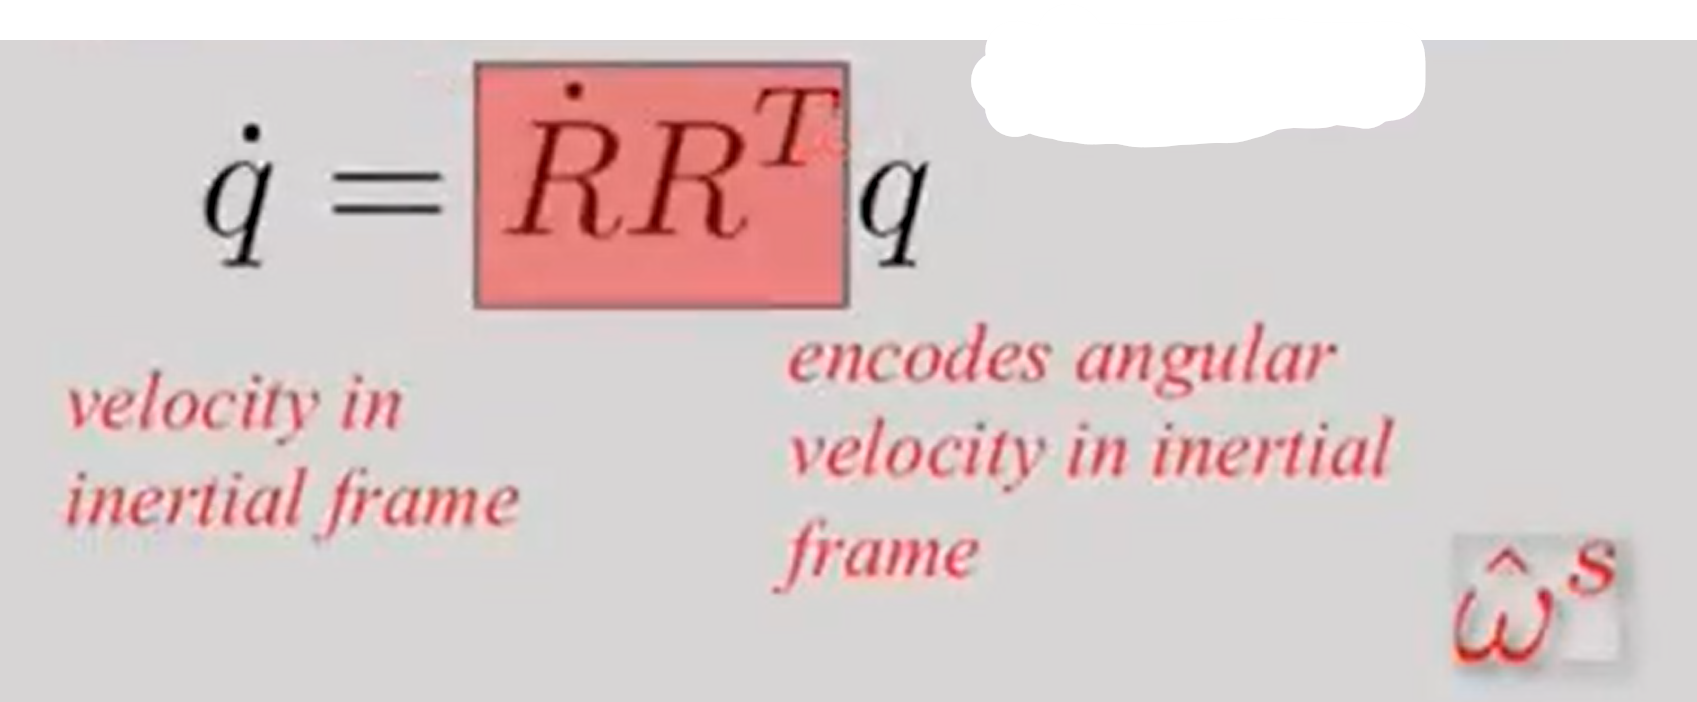

which relates inertial angular rates ($\omega_s$) to inertial velocity (transitional).

### 
$${\omega_s \;=\dot{\;R} \left(t\right)R}^T \left(t\right)$$


## Examples

### Example 1: angular velocity for rotation around Z-axis

R = R1_z

$$R(t) = \left(\begin{array}{ccc} \cos\left(\psi \left(t\right)\right) & -\sin\left(\psi \left(t\right)\right) & 0\\ \sin\left(\psi \left(t\right)\right) & \cos\left(\psi \left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_dot = diff(R,t)

$$R\_dot(t) = \left(\begin{array}{ccc} -\sin\left(\psi \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right) & -\cos\left(\psi \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right) & 0\\ \cos\left(\psi \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right) & -\sin\left(\psi \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right) & 0\\ 0 & 0 & 0 \end{array}\right)$$

omega_b = simplify(R.'*R_dot)

$$omega\_b(t) = \left(\begin{array}{ccc} 0 & -\frac{\partial }{\partial t}\psi \left(t\right) & 0\\ \frac{\partial }{\partial t}\psi \left(t\right) & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

omega_w = simplify(R_dot*R.')

$$omega\_w(t) = \left(\begin{array}{ccc} 0 & -\frac{\partial }{\partial t}\psi \left(t\right) & 0\\ \frac{\partial }{\partial t}\psi \left(t\right) & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

Which results in a angular velocity around z-axis only ($\left\lbrack \begin{array}{c}
0\\
0\\
\dot{\;\;\psi \;} 
\end{array}\right\rbrack$

### Example 2: angular velocity for rotation sequence Z-X

R = R1_z*R2_x

$$R(t) = \left(\begin{array}{ccc} \cos\left(\psi \left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right) & \sin\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\\ \sin\left(\psi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\psi \left(t\right)\right) & -\cos\left(\psi \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\\ 0 & \sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right) \end{array}\right)$$

R_dot = simplify(diff(R,t));
omega_b = simplify(R.'*R_dot)

$$omega\_b(t) = \left(\begin{array}{ccc} 0 & -\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right) & \sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\\ \cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right) & 0 & -\frac{\partial }{\partial t}\varphi \left(t\right)\\ -\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right) & \frac{\partial }{\partial t}\varphi \left(t\right) & 0 \end{array}\right)$$

Another manual way using $\omega_b ={\left(R_z R_x \right)}^T *\left(\dot{\;R_z \;} R_x +R_z \dot{\;\;R_x } \right)$

% another way to calculate it manually
w_b2 = simplify( (R1_z*R2_x).'*(diff(R1_z,t)*R2_x + R1_z*diff(R2_x,t)) )

$$w\_b2(t) = \left(\begin{array}{ccc} 0 & -\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right) & \sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\\ \cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right) & 0 & -\frac{\partial }{\partial t}\varphi \left(t\right)\\ -\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right) & \frac{\partial }{\partial t}\varphi \left(t\right) & 0 \end{array}\right)$$

omega_w = simplify(R_dot*R.')

$$omega\_w(t) = \left(\begin{array}{ccc} 0 & -\frac{\partial }{\partial t}\psi \left(t\right) & \sin\left(\psi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ \frac{\partial }{\partial t}\psi \left(t\right) & 0 & -\cos\left(\psi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ -\sin\left(\psi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right) & \cos\left(\psi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right) & 0 \end{array}\right)$$

### Example 3: angular velocity for rotation sequence Z-X-Y

R = R1_z*R2_x*R3_y

$$R(t) = \left(\begin{array}{ccc} \cos\left(\psi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)-\sin\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right) & \cos\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)+\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\\ \cos\left(\theta \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)+\cos\left(\psi \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\psi \left(t\right)\right) & \sin\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-\cos\left(\psi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\\ -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & \sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) \end{array}\right)$$

R_dot = simplify(diff(R,t));
omega_b = simplify(R.'*R_dot);
omega_b = omega_b(t)

Another manual way using $\omega_b ={\left(R_z R_x R_y \right)}^T *\left(\dot{\;R_z \;} R_x R_y +R_z \dot{\;\;R_x } R_y +R_z R_x \dot{\;\;R_y } \right)$

% another way to calculate it manually
w_b2 = simplify( (R1_z*R2_x*R3_y).'*(diff(R1_z,t)*R2_x*R3_y + R1_z*diff(R2_x,t)*R3_y + R1_z*R2_x*diff(R3_y,t)) )

omega_w = simplify(R_dot*R.');
omega_w = omega_w(t)

TO confirm, substitute a zero rotation around Y, we should get the same as Z-X angular velocity

simplify(subs(omega_b,[theta(t)],[0]))

$$ans = \left(\begin{array}{ccc} 0 & -\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right) & \sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\\ \cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right) & 0 & -\frac{\partial }{\partial t}\varphi \left(t\right)\\ -\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right) & \frac{\partial }{\partial t}\varphi \left(t\right) & 0 \end{array}\right)$$

## Euler rates to body rates conversion matrix

Extract the vector from the skew-symmetric matrix

w_x = simplify(omega_b(3,2));
w_y = simplify(omega_b(1,3));
w_z = simplify(omega_b(2,1));
wb = [w_x;w_y;w_z];

Substitute with shorter symbols

syms phi_t theta_t psi_t phi_dot_t theta_dot_t psi_dot_t
cur_labels = [phi(t), theta(t), psi(t),diff(phi(t), t), diff(theta(t), t),diff(psi(t), t) ];
new_labels = [phi_t, theta_t, psi_t, phi_dot_t, theta_dot_t, psi_dot_t];
wb_new = subs(wb,cur_labels,new_labels);
% simplify the expressions
wb_new = simplify(wb_new)

$$wb\_new = \left(\begin{array}{c} {\dot{\varphi }}_{t}\,\cos\left(\theta_{t}\right)-{\dot{\psi }}_{t}\,\cos\left(\varphi_{t}\right)\,\sin\left(\theta_{t}\right)\\ {\dot{\theta }}_{t}+{\dot{\psi }}_{t}\,\sin\left(\varphi_{t}\right)\\ {\dot{\varphi }}_{t}\,\sin\left(\theta_{t}\right)+{\dot{\psi }}_{t}\,\cos\left(\varphi_{t}\right)\,\cos\left(\theta_{t}\right) \end{array}\right)$$

# References

- Direction Cosine Matrix IMU: Theory William Premerlani and Paul Bizard: [https://wiki.paparazziuav.org/w/images/e/e5/DCMDraft2.pdf](https://wiki.paparazziuav.org/w/images/e/e5/DCMDraft2.pdf)

-  Representing Attitude: Euler Angles, Unit Quaternions, and Rotation Vectors, James Diebel  (2006)

- `Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`